# Regression

clear; clc;
cd('/Users/duncan/Documents/GitHub/Advanced-Biomedical-Experimental-Design-and-Statistics/Regression')

## Calculate B's

weight = [55,61,67,83,65,82,70,58,65,61];
height = [140,150,152,220,190,195,175,130,155,160];
B1 = sum((weight - mean(weight)) .* (height - mean(height))) / sum((weight - mean(weight)).^2)

B1 = 2.6069

B0 = mean(height) - B1 * mean(weight)

B0 = -7.1769

## Bivariate Prediction

weight_bob = 80;
height_bob = B0 + B1 * weight_bob

height_bob = 201.3711

## Bivariate - Standard Error of Estimate

SE = sqrt(sum((height - (B0 + B1 .* weight)).^2) / (length(weight) - 2))

SE = 14.1141

## Correlation Coefficient (r)

r = sum((weight - mean(weight)) .* (height - mean(height))) / (sqrt(sum((weight - mean(weight)).^2)) * sqrt(sum((height - mean(height)).^2)))

r = 0.8786

corr(height', weight')

ans = 0.8786

## Coefficient of Determination (r^2)

rsquared = corr(height', weight')^2

rsquared = 0.7720

## Bivariate Regression - Significance Test Cont'd

N = length(weight);
Fstat0 = (r*r*(N-2)) / (1-(r*r))

Fstat0 = 27.0896

pval0 = 1 - cdf('f', Fstat0, 1, N-2)

pval0 = 8.1763e-04

dataTable2 = table(height', weight', 'VariableNames', {'height', 'weight'})

dataTable2 = 10×2 table
    height    weight
    ______    ______
     140        55  
     150        61  
     152        67  
     220        83  
     190        65  
     195        82  
     175        70  
     130        58  
     155        65  
     160        61  

lmModel = fitlm(dataTable2, 'weight~height')

lmModel = Linear regression model:
    weight ~ 1 + height

Estimated Coefficients:
                   Estimate       SE       tStat       pValue  
                   ________    ________    ______    __________
    (Intercept)     17.332       9.6037    1.8048       0.10876
    height         0.29615     0.056899    5.2048    0.00081763

Number of observations: 10, Error degrees of freedom: 8
Root Mean Squared Error: 4.76
R-squared: 0.772,  Adjusted R-Squared: 0.744
F-statistic vs. constant model: 27.1, p-value = 0.000818

lmModel.Coefficients.Estimate(1) % B_0, coefficient

ans = 17.3322

lmModel.Coefficients.Estimate(2) % B_1, coefficient

ans = 0.2961

lmModel.Coefficients.pValue(2) % p-value

ans = 8.1763e-04

lmModel.Rsquared % r^2 of model 

ans = struct with fields:
    Ordinary: 0.7720
    Adjusted: 0.7435

## Regression - Nonlinear

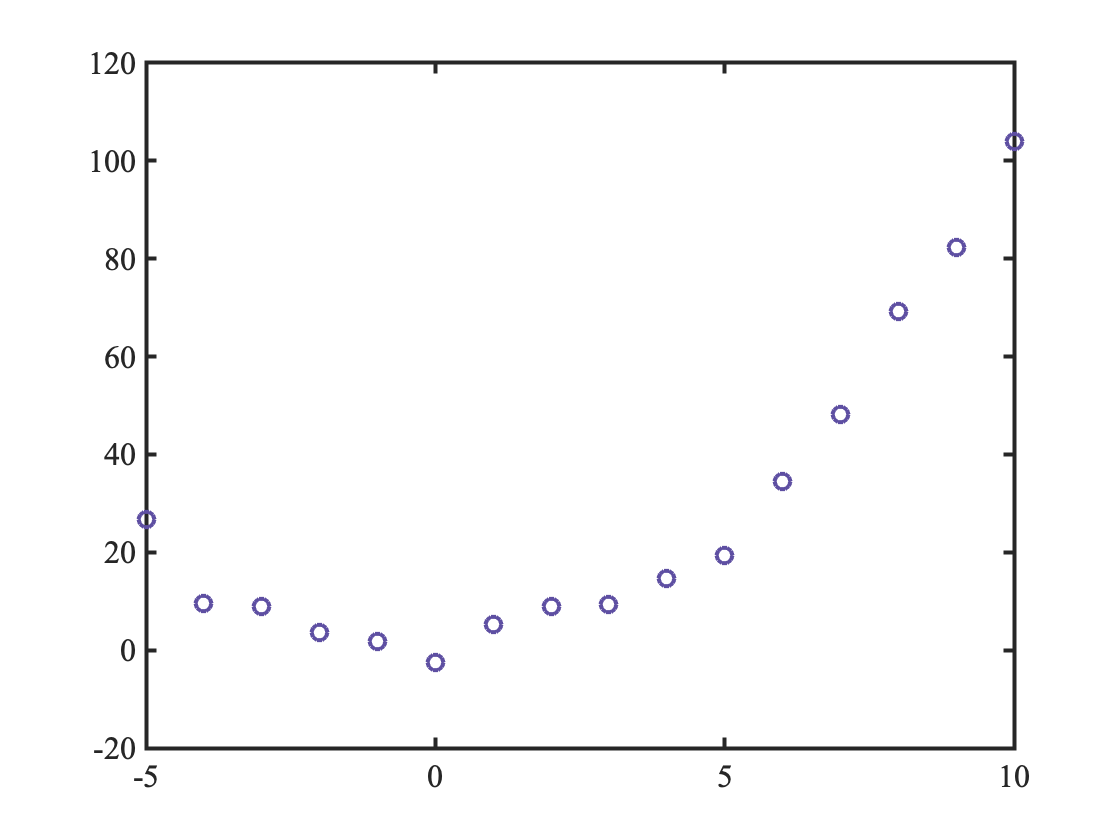

X = [-5,-4,-3,-2,-1,0,1,2,3,4,5,6,7,8,9,10]';
y = X.^2 + normrnd(0,3, [16 1]);
figure();
plot(X,y,'o', 'markersize', 8);

dataTable2 = table(X, y, 'variablenames', {'X', 'y'}); 
m2 = fitlm(dataTable2, 'y~X')

m2 = Linear regression model:
    y ~ 1 + X

Estimated Coefficients:
                   Estimate      SE      tStat       pValue  
                   ________    ______    ______    __________
    (Intercept)      14.74     5.9247    2.4878      0.026073
    X               5.1991     1.1298    4.6019    0.00041101

Number of observations: 16, Error degrees of freedom: 14
Root Mean Squared Error: 20.8
R-squared: 0.602,  Adjusted R-Squared: 0.574
F-statistic vs. constant model: 21.2, p-value = 0.000411

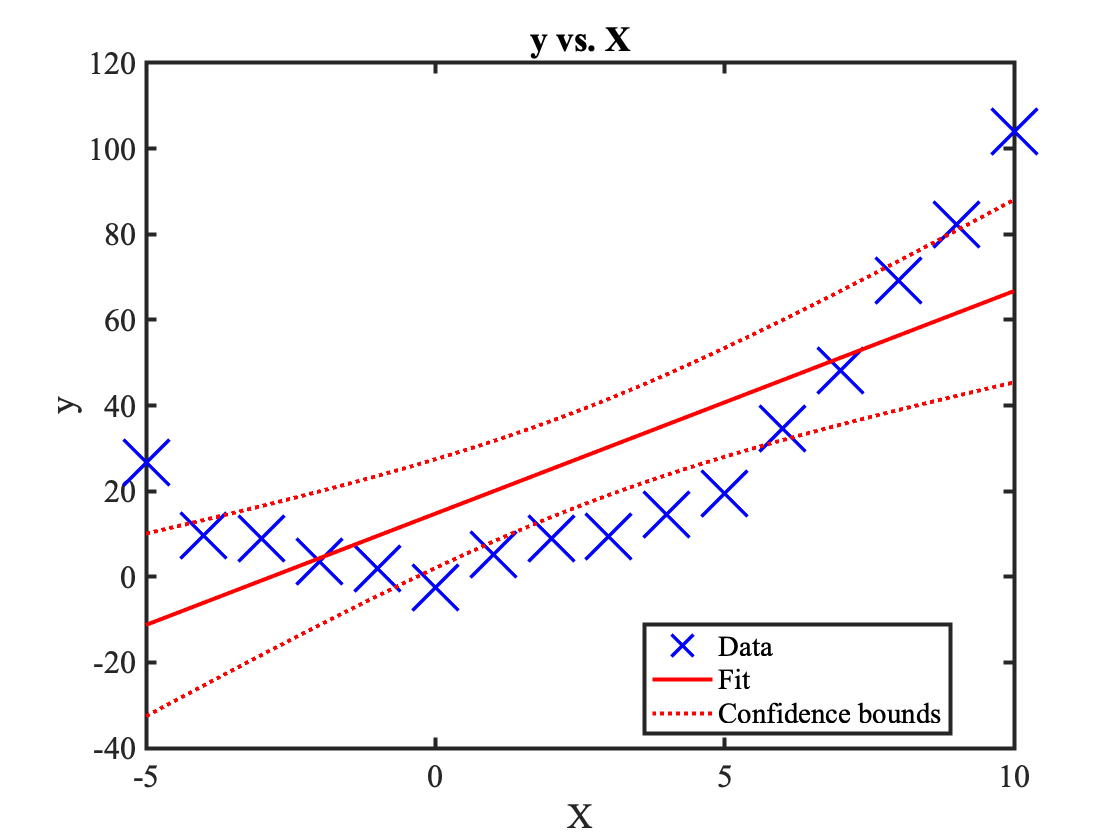

plot(m2)

Xsquared = X.^2;
dataTable0 = table(Xsquared, y, 'variablenames', {'Xsquared', 'y'}); 
m0 = fitlm(dataTable0, 'y~Xsquared')

m0 = Linear regression model:
    y ~ 1 + Xsquared

Estimated Coefficients:
                   Estimate       SE        tStat        pValue  
                   ________    ________    ________    __________
    (Intercept)    -0.61443       1.151    -0.53382       0.60184
    Xsquared          1.031    0.028383      36.323    2.9602e-15

Number of observations: 16, Error degrees of freedom: 14
Root Mean Squared Error: 3.38
R-squared: 0.99,  Adjusted R-Squared: 0.989
F-statistic vs. constant model: 1.32e+03, p-value = 2.96e-15

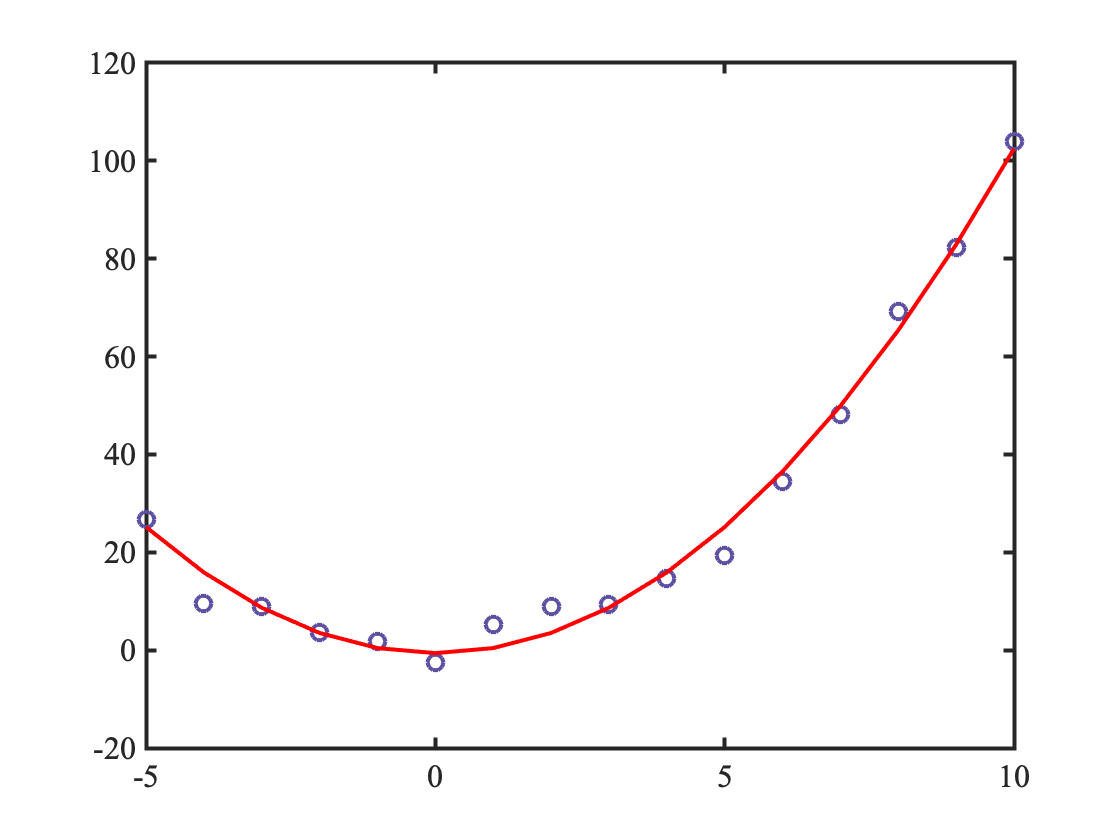

yfit = m0.predict(Xsquared);
figure();
plot(X,y,'o', 'markersize', 8);
hold on 
plot(X,yfit,'r-')

## Multiple Regression

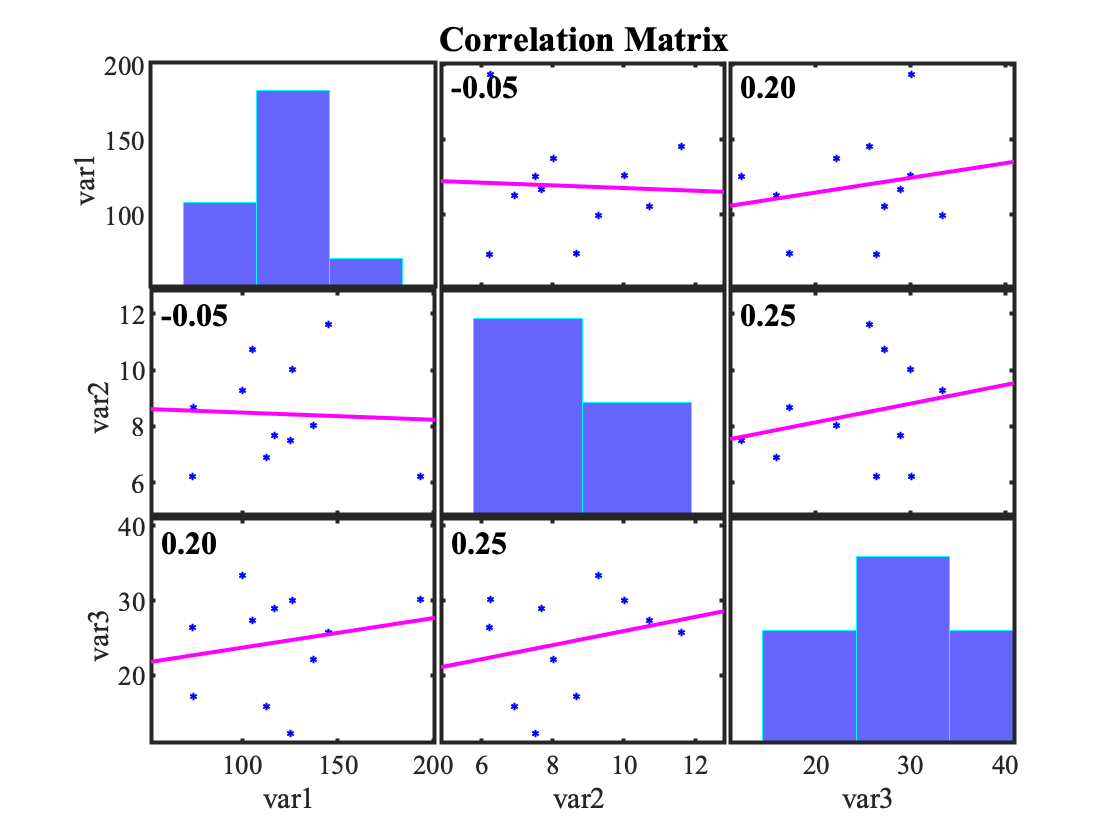

% this won't line up because I can't copy all of the data, it gets cut off 
W = [193.6, 137.5, 145.4, 117, 105.4, 99.9, 74, 74.4, 112.8, 125.4, 126.5]';
P = [6.24, 8.03, 11.62, 7.68, 10.72, 9.28, 6.23, 8.67, 6.91, 7.51, 10.01]';
S = [30.1, 22.2, 25.7, 28.9, 27.3, 33.4, 26.4, 17.2, 15.9, 12.2, 30.]';
data0 = [W, P, S]; 

figure(); 
corrplot(data0);

corr(data0)

ans =     1.0000   -0.0477    0.1962
   -0.0477    1.0000    0.2499
    0.1962    0.2499    1.0000


dataTable3 = table(W, P, S, 'variablenames', {'W', 'P', 'S'});
m3 = fitlm(dataTable3, 'W ~ S + P')

m3 = Linear regression model:
    W ~ 1 + P + S

Estimated Coefficients:
                   Estimate      SE       tStat      pValue 
                   ________    ______    ________    _______
    (Intercept)     108.55     62.918      1.7253    0.12275
    P              -1.9334     6.6734    -0.28972    0.77939
    S               1.1044     1.7719     0.62331    0.55043

Number of observations: 11, Error degrees of freedom: 8
Root Mean Squared Error: 36.7
R-squared: 0.0485,  Adjusted R-Squared: -0.189
F-statistic vs. constant model: 0.204, p-value = 0.82

m3.Coefficients.Estimate(1) % intercept coefficient 

ans = 108.5542

m3.Coefficients.Estimate(3) % S coefficient 

ans = 1.1044

m3.Coefficients.Estimate(2) % P coefficient

ans = -1.9334

m3.Coefficients.pValue(3) % S p-value

ans = 0.5504

m3.Coefficients.pValue(2) % P p-value

ans = 0.7794

m3.Rsquared % r^2 of model 

ans = struct with fields:
    Ordinary: 0.0485
    Adjusted: -0.1894

## Stepwise - Multiple Regression

mbest = stepwiselm(dataTable3, 'W ~ S + P')

1. Removing P, FStat = 0.08394, pValue = 0.77939
2. Removing S, FStat = 0.36041, pValue = 0.56309


mbest = Linear regression model:
    W ~ 1

Estimated Coefficients:
                   Estimate      SE      tStat       pValue  
                   ________    ______    ______    __________
    (Intercept)     119.26     10.139    11.763    3.5227e-07

Number of observations: 11, Error degrees of freedom: 10
Root Mean Squared Error: 33.6

## Nonparametric - Spearman's

IQ = [86, 97, 99, 100, 101, 103, 106, 110, 112, 113];
TVhours = [2, 20, 28, 27, 50, 29, 7, 17, 6, 12];
dsquared = [0, 16, 25, 9, 25, 9, 16, 9, 49, 36];
N = length(IQ);
rho = 1 - (6 * sum(dsquared)) / (N*(N^2-1))

rho = -0.1758

Fstat1 = (rho^2*(N-2)) / (1-(rho^2));
% Area under F-Distribution, using pf() function
pval1 = 1 - cdf('f', Fstat1, 1, N-2) % Fstat, parameters (k - 1), df (N - k)

pval1 = 0.6272


[rho, pval] = corr(IQ', TVhours', 'type', 'Spearman')

rho = -0.1758

pval = 0.6320